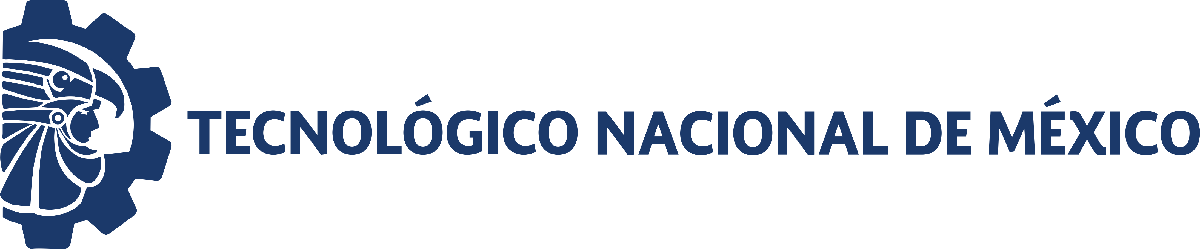                                 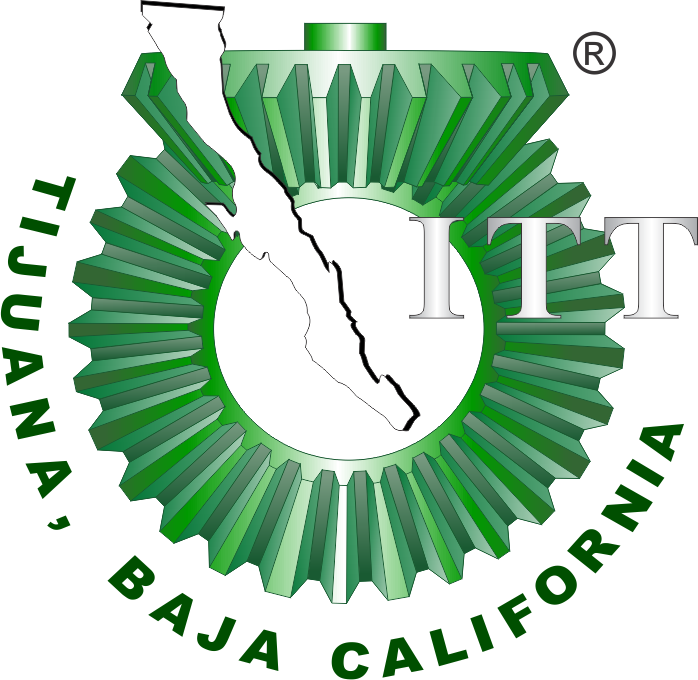

#                                                                             Práctica 4: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

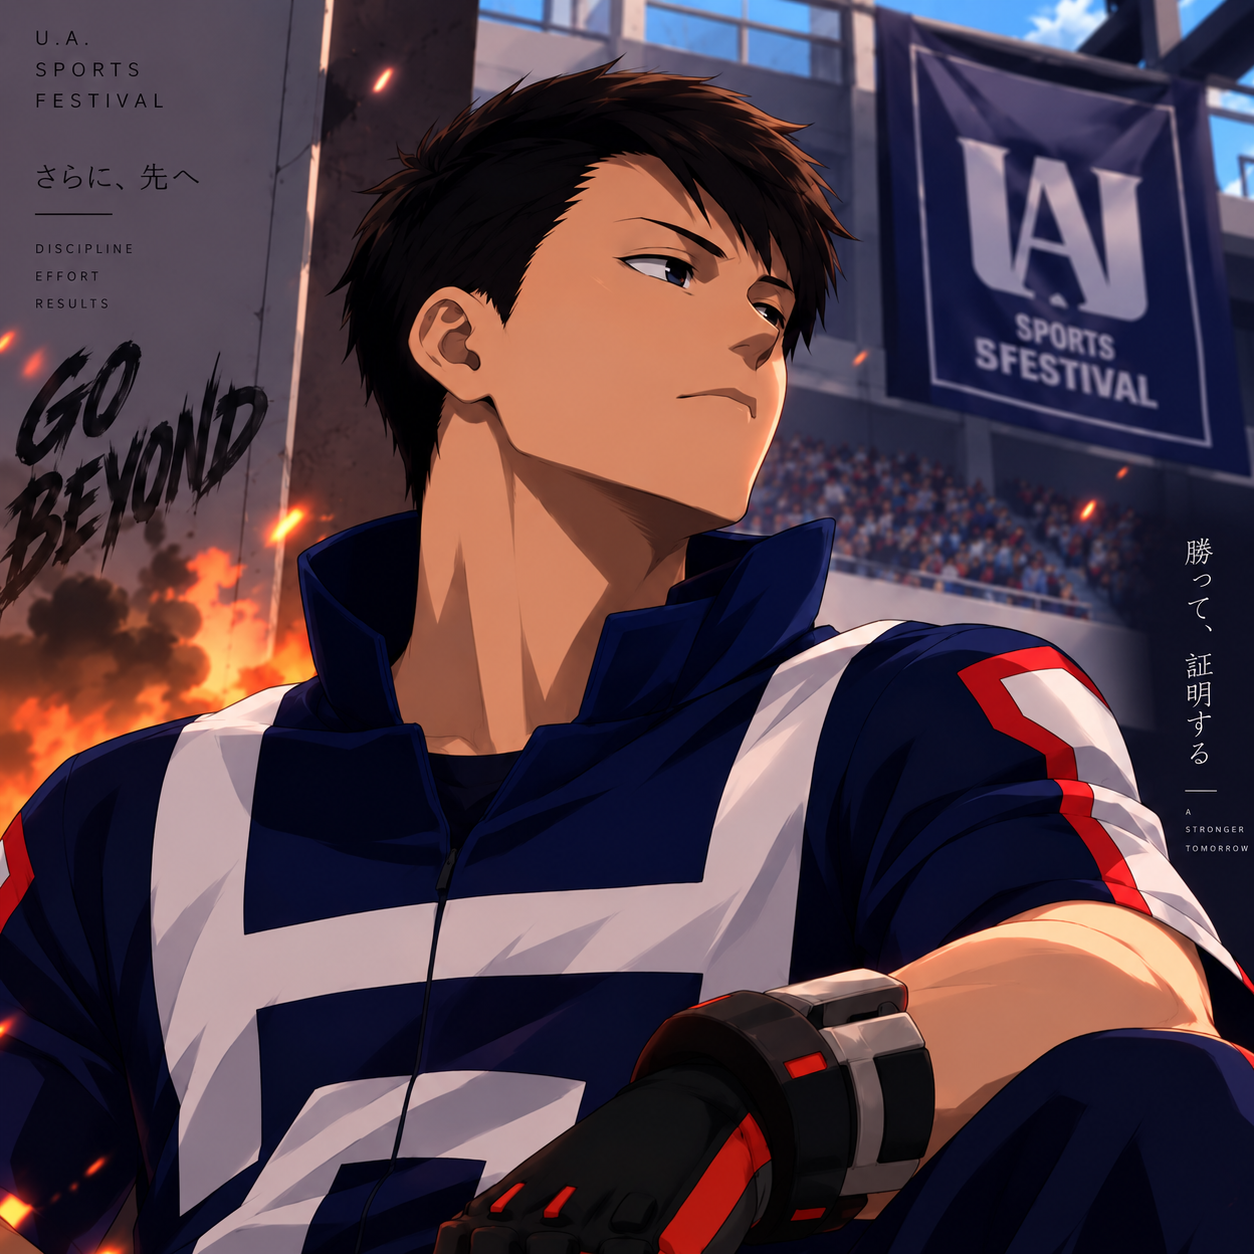

Nombre del alumno: Kevin Rodriguez Padilla

Número de control: 22210428

Correo institucional: l22210428**@tectijuana.edu.mx**

Asignatura:   Modelado de Sistemas Fisiológicos

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('systemPRAC44.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('systemPRAC44.slx', parameters);

## **Respuesta al impulso: Control y caso**

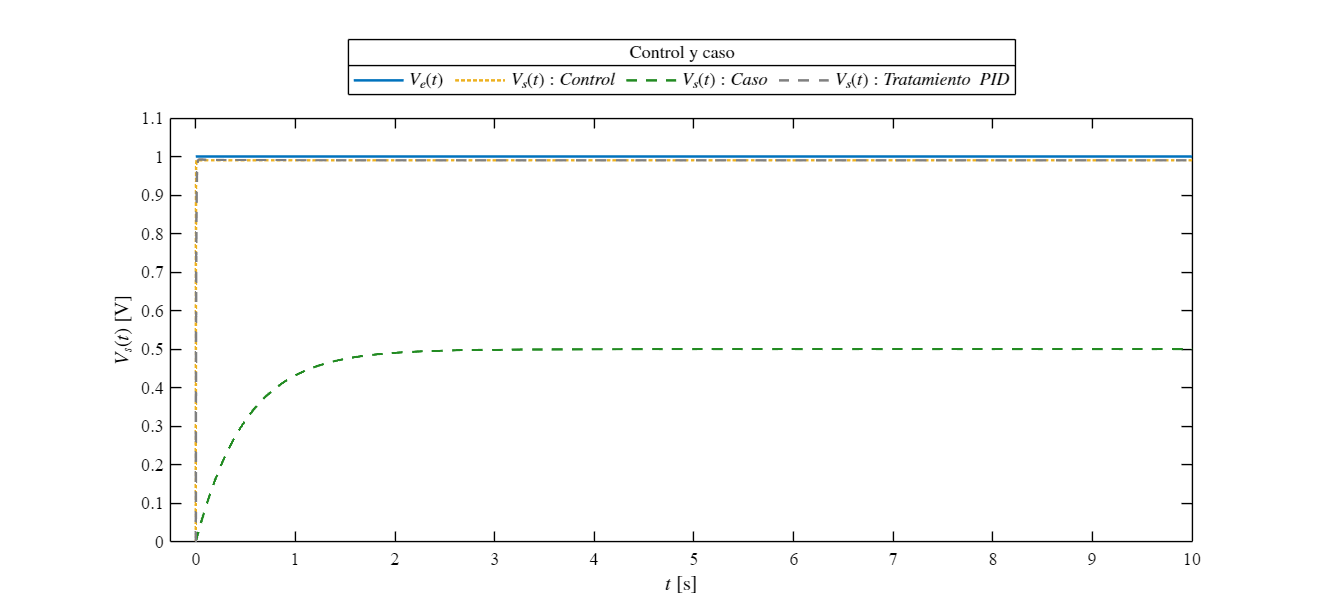

plotsignals(x.t,x.Ve,x.VsControl,x.Fs1,x.VsPID)

function plotsignals(t,c,c1,c2,c3)

% Crear figura con fondo blanco
fig = figure('Color','w');
set(fig,'Units','inches','Position',[1,1,11,5], ...
    'InvertHardcopy','off');

% Configurar ejes con fondo blanco
ax = axes('Parent',fig);

set(ax,'FontName','Times New Roman', ...
    'FontSize',11, ...
    'Color','w', ...
    'XColor','k', ...
    'YColor','k', ...
    'GridColor','k', ...
    'Box','on');

hold(ax,'on');
grid(ax,'off');

% Colores
clr1 = [0,114,189]/255;
clr2 = [237,177,32]/255;
clr3 = [34,139,34]/255;
clr4 = [128,128,128]/255;

order = [clr1;clr2;clr3;clr4];
colororder(ax,order)

% Graficar señales
plot(ax,t,c,'-', ...
    t,c1,':', ...
    t,c2,'--', ...
    t,c3,'--', ...
    'LineWidth',1.5, ...
    'MarkerSize',5, ...
    'MarkerIndices',1:1e3:length(t));

% Leyenda
L = legend(ax,'$V_e(t)$', ...
    '$V_s(t): Control$', ...
    '$V_s(t): Caso$', ...
    '$V_s(t): Tratamiento\ PID$');

set(L,'Interpreter','latex', ...
    'Location','northoutside', ...
    'Orientation','horizontal', ...
    'Color','w', ...
    'TextColor','k', ...
    'EdgeColor','k', ...
    'FontSize',11);

title(L,'Control y caso','Color','k')

% Etiquetas
xlabel(ax,'$t$ [s]', ...
    'Interpreter','latex','Color','k')

ylabel(ax,'$V_s(t)$ [V]', ...
    'Interpreter','latex','Color','k')

% Límites
xlim(ax,[-0.25 10]);
xticks(ax,0:1:10)

ylim(ax,[0 1.1]);
yticks(ax,0:0.1:1.1)

% Exportar PDF con fondo blanco
exportgraphics(fig,'Control_caso_matlab.pdf', ...
    'ContentType','vector', ...
    'BackgroundColor','white')

end